## Introduction to inner product and convolution

First: Matrix multiplication

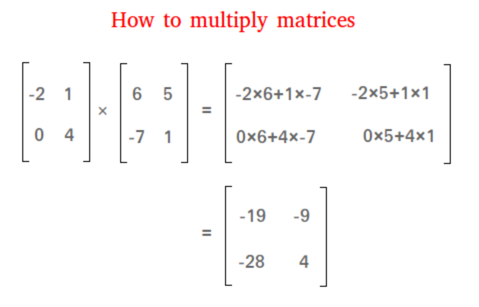

Matrices M1 and M2 are multiplied by multiplying the row elements of M1 with the column elements of M2, and the results added for each row/column pair. 

The sign for this is *

In Matlab, * is matrix multiplication and .* is elementwise individual multiplication without any addition. 

In this process, the inner dimensions get lost: 

The product of 2 M1 and M2 exists only if the number of columns of M1 (the second dimension) is equal to the number of rows of M2 (its first dimension).

a = rand(3,2)

a =     0.6787    0.3922
    0.7577    0.6555
    0.7431    0.1712


size(a)

ans =      3     2


b = rand (2,3)

b =     0.7060    0.2769    0.0971
    0.0318    0.0462    0.8235


size(b)

ans =      2     3


The results has dimensions of rows of M1 and columns of M2 (again, the "inner" dimensions are lost, - but not the data of course)

c = a * b 

c =     0.4917    0.2061    0.3889
    0.5559    0.2401    0.6134
    0.5301    0.2137    0.2131


size(c)

ans =      3     3


more examples with randome number matrices. 

what will the new dimensions be? 

rand(4,3) * rand(3,1)

rand(2,1) * rand(1,10)

rand(2,1) * rand(1,1)

[https://timeseriesreasoning.com/contents/deep-dive-into-variance-covariance-matrices/](https://timeseriesreasoning.com/contents/deep-dive-into-variance-covariance-matrices/)

inner product: 

matrix multiplication of two vectors of the same length, one is a row, one is a column vector

a1 = rand(1,4)
a2 = rand(4,1)

one more time, two vectors

a1 = [-1 1 -1 1]

a1 =     -1     1    -1     1


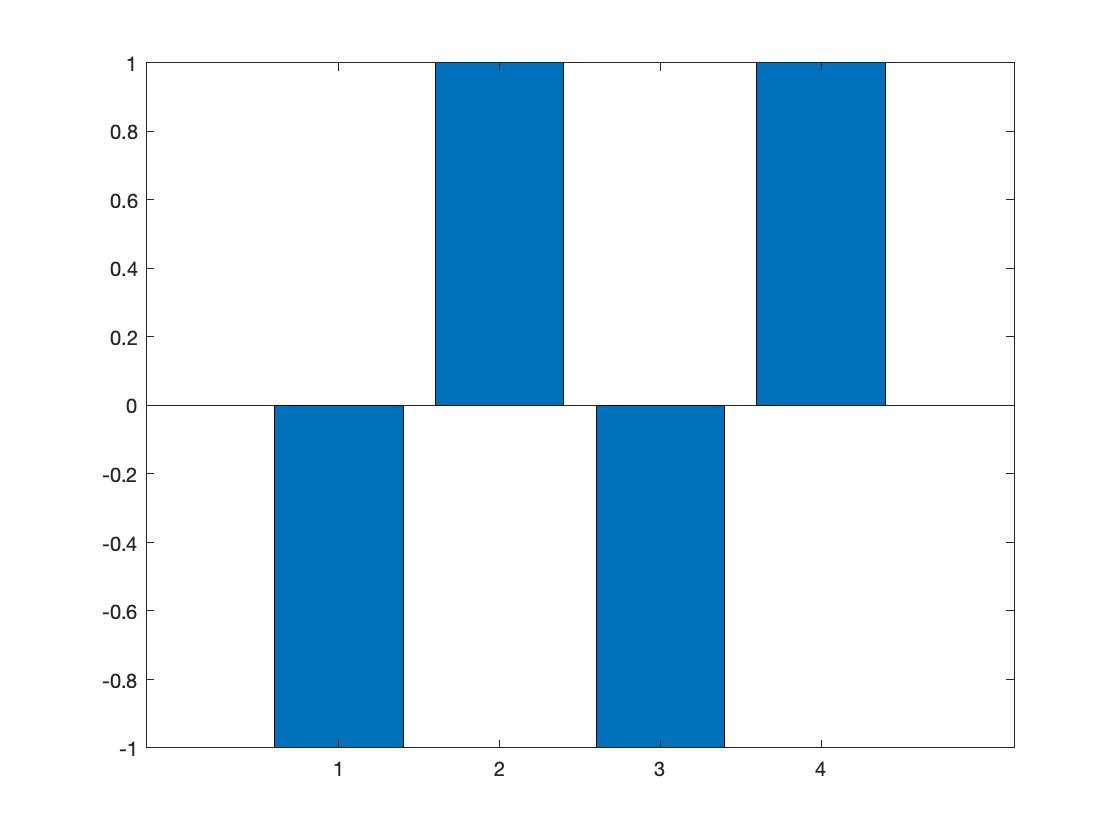

figure, bar(a1)

a2 = [-1 -1 1 1]

a2 =     -1    -1     1     1


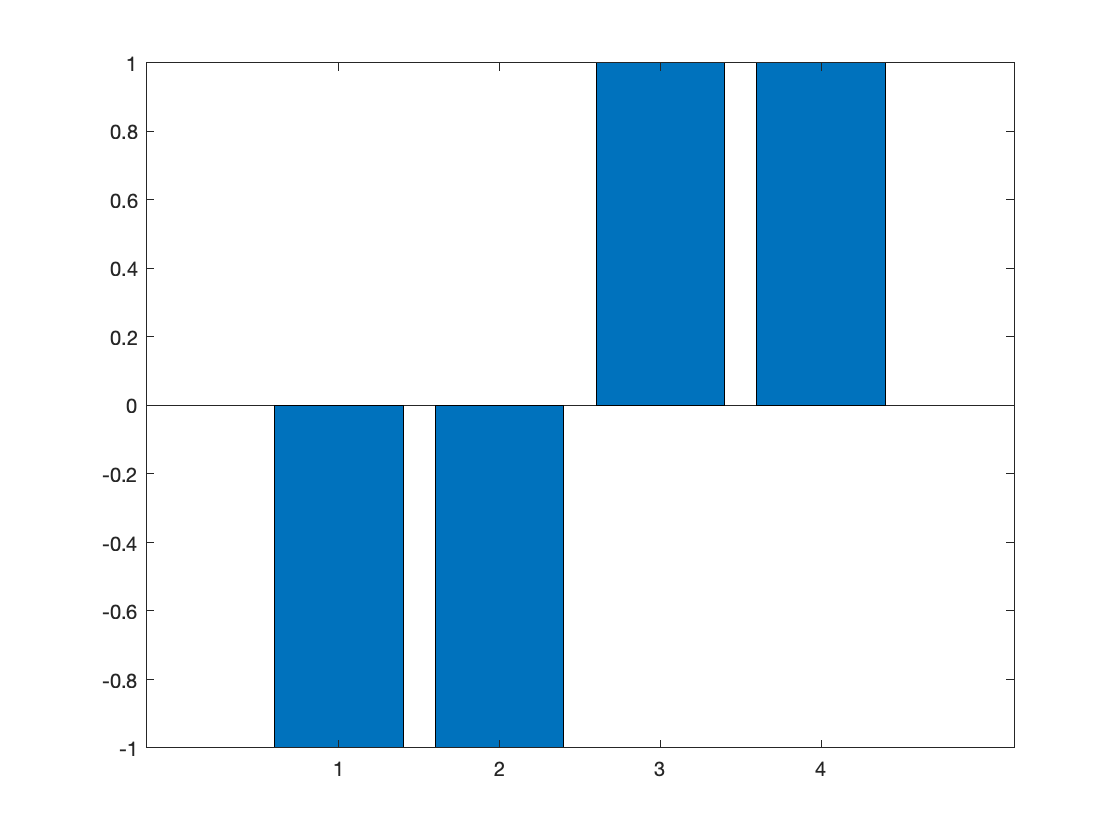

figure, bar(a2)

The inner product between those two vectors

c = a1*a2'

c = 0

so, the inner product is a measure of similarity between two vectors, it is high when they are similar, and low when they are not. In fact, the inner product is like an unscaled correlation coefficient. Let's try this

one more time, two vectors

a1 = [-1 1 -1 1]

a1 =     -1     1    -1     1


figure, bar(a1)

a2 = [-1 .5 -1 1]

a2 =    -1.0000    0.5000   -1.0000    1.0000


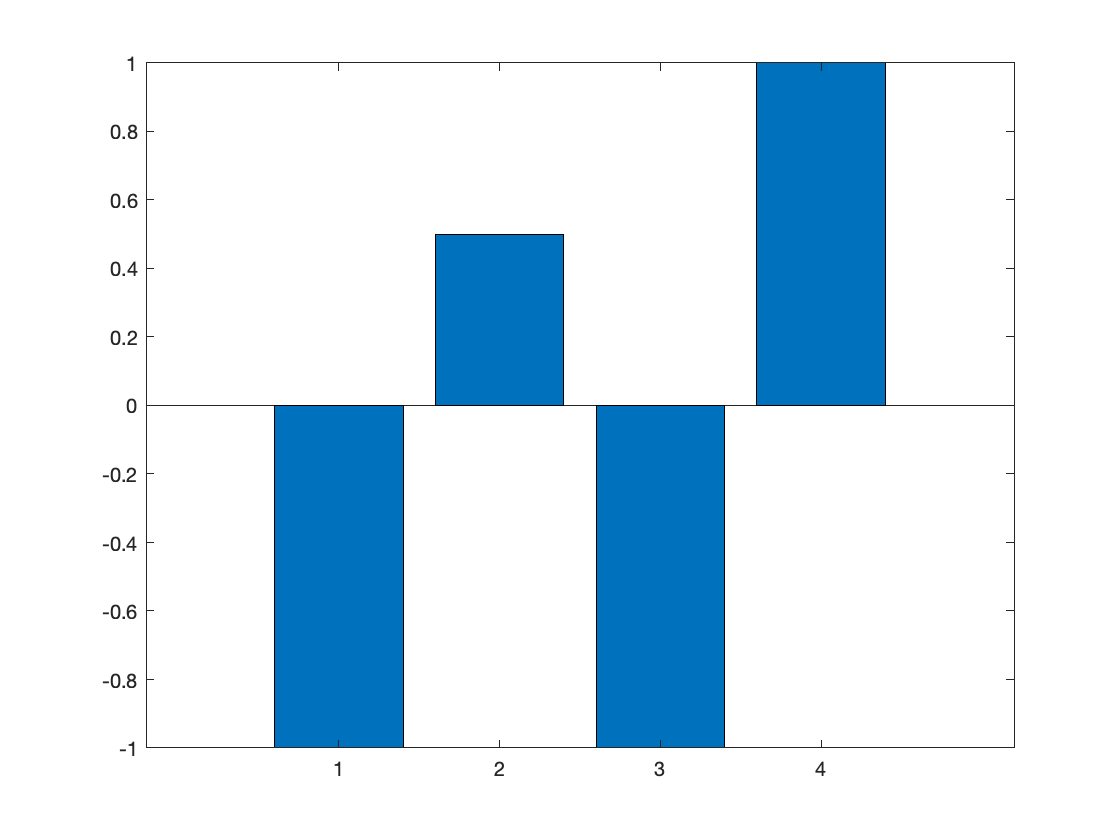

figure, bar(a2)

The inner product between those two vectors

c = a1*a2'

c = 3.5000